# Taller 8

### 26/09/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 5 y 6*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

- **Otros recursos sobre manejo de MATLAB practicas básicas: ***https://matlabacademy.mathworks.com/es/*

*Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.*

### Integración

*Desarrollaremos el octavo taller, para esta sección resolveremos *$3,4,5,6,8,11$.

**3. **Práctica con las rutinas de la clase `traprl.m` y `simprl.m`. Recuerden que en la regla de Simpson, el número de subintervalos debe ser un número par. Utilice ambas rutinas para aproximar las siguientes integrales con el número de subintervalos dado: 

**  a)   **$\int_1^3 \frac{x}{x^2 +4}\textrm{dx}$ : $n=8$

**  b)   **$\int_e^{e+2} \frac{1}{x\;\log \left(x\right)}\textrm{dx}$ : $n=8$

clear

f = @(x) x ./ (x.^2 + 4);
a = 1; b = 3; n = 8;

ISimp = simprl(f, a, b, n), ITrap = traprl(f, a, b, n)

ISimp = 0.4778

ITrap = 0.4770

I = integral(f, a, b)

I = 0.4778

f = @(x) 1 ./ (x .* log(x));
a = exp(1); b = exp(1) + 2; n = 8;

ISimp = simprl(f, a, b, n), ITrap = traprl(f, a, b, n)

ISimp = 0.4392

ITrap = 0.4403

I = integral(f, a, b)

I = 0.4392

**4.** Un carro recorre un trayecto E de carretera en 84s. La velocidad del carro se mide cada* 6 segundos* por medio de una pistola-radar y está dada en las siguientes tablas en metros/segundos: 

`Tiempo (s)       `` 0     6     12    18    24    30    36    42    48    54    ...`

`Velocidad (m/s)   ``37    40    44    46    44    39    36    32    29    25    ...`

`...    Tiempo (s)        ``60    66    72    78    84`

`...    Velocidad (m/s)   ``23    26    31    34    36`

Aproxime la longitud del trayecto ***E*** o sea la integral  $\int_0^{84} v\left(t\right)\;\textrm{dt}$ por medio de la* regla de Simpson*

`Nota: ``Recordemos que la regla de simpson compuesta está dada por`


$$\int_a^b f\left(x\right)\;\textrm{dx}=\frac{h}{3}\;\left\lbrack f\left(x_0 \right)+4\;\sum_{i=1}^{n\;/\;2} f\left(x_{2i-1} \right)\;+2\;\sum_{i=1}^{n\;/\;2-1} f\left(x_{2i} \right)\;+f\left(x_n \right)\right\rbrack -\frac{h^4 }{180}\left(b-a\right)f^{\left(\textrm{iv}\right)} \left(\xi \right)$$


clear

t = 0:6:84;
v = [37 40 44 46 44 39 36 32 29 25 23 26 31 34 36];

% Método númerico / Programativo bajo nivel
h = 6;
Spar = 0;
Simpar = -v(1);

for k = 1:7
    Spar = Spar + v(2*k);
    Simpar = Simpar + v(2*k - 1);
end

I = h / 3 * (v(1) + 4*Spar + 2*Simpar + v(end))

I = 2910

% Método Programativo de alto nivel
help griddedInterpolant

 griddedInterpolant   Gridded data interpolant
    F = griddedInterpolant creates an empty gridded data interpolant.
 
    F = griddedInterpolant(x,v) creates a 1-D interpolant F from a vector
    of sample points x and a vector of values v. F satisfies v = F(x).
 
    F = griddedInterpolant(X1,X2,...,Xn,V) creates an N-D interpolant using
    a grid of sample points specified by n N-D arrays Xi created from grid
    vectors xig using [X1,X2,...,Xn] = NDGRID(x1g,x2g,...,xng). V must have
    the same size as the Xi arrays. F satisfies V = F(X1,X2,...,Xn).
 
    F = griddedInterpolant({x1g,x2g,...,xng},V) specifies a grid in compact
    form using grid vectors xig. LENGTH(xig) must equal SIZE(V,i). Use this
    syntax to conserve memory when the sample points form a large grid.
    The interpolant F satisfies V = F({x1g,x2g,...,xng}).
 
    F = griddedInterpolant(V) uses an implicit gri

f = griddedInterpolant(t, v)

f =   griddedInterpolant with properties:

            GridVectors: {[0 6 12 18 24 30 36 42 48 54 60 66 72 78 84]}
                 Values: [37 40 44 46 44 39 36 32 29 25 23 26 31 34 36]
                 Method: 'linear'
    ExtrapolationMethod: 'linear'


f = @(t) f(t)

f = function_handle with value:
    @(t)f(t)


I = simprl(f, 0, 84, 14)

I = 2910

% Método Interno de MATLAB
table = cumtrapz(t, v);
I = table(end)

I = 2913

I = trapz(v) % Integral Unitaria

I = 485.5000

I = h * I    % Integral escalada

I = 2913

**5. **Encuentre el grado de precisión para cada una de las siguientes reglas de integración para la integral


$$\int_{-1}^1 f\left(x\right)\;\textrm{dx}$$


**    a)    **$f\left(-1\right)+f\left(1\right)$*    // Ejercicio propuesto de tarea*

**    b)    **$\frac{2}{3}\left\lbrace f\left(-1\right)+f\left(0\right)+f\left(1\right)\right\rbrace$

**    c)    **$f\left(-\frac{1}{\sqrt{3}}\right)+f\left(\frac{1}{\sqrt{3}}\right)$

clear
syms f(x)
syms x real

% Polinomio grado 0
f(x) = x^0;
Eq = int(f, -1, 1) == 2/3 * (f(-1) + f(0) + f(1))

$$Eq1 = 2=2$$

% Polinomio grado 1
f(x) = x^1;
Eq = int(f, -1, 1) == 2/3 * (f(-1) + f(0) + f(1))

$$Eq1 = 0=0$$

% Polinomio grado 2
f(x) = x^2;
Eq = int(f, -1, 1) == 2/3 * (f(-1) + f(0) + f(1))

$$Eq1 = \frac{2}{3}=\frac{4}{3}$$

La regla de integración** b) **cumple hasta grado 1.

% Polinomio grado 0
f(x) = x^0;
Eq = int(f, -1, 1) == f(-1/sqrt(3)) + f(1/sqrt(3))

$$Eq1 = 2=2$$

% Polinomio grado 1
f(x) = x^1;
Eq = int(f, -1, 1) == f(-1/sqrt(3)) + f(1/sqrt(3))

$$Eq1 = 0=0$$

% Polinomio grado 2
f(x) = x^2;
Eq = int(f, -1, 1) == f(-1/sqrt(3)) + f(1/sqrt(3))

$$Eq1 = \frac{2}{3}=\frac{2}{3}$$

% Polinomio grado 3
f(x) = x^3;
Eq = int(f, -1, 1) == f(-1/sqrt(3)) + f(1/sqrt(3))

$$Eq1 = 0=0$$

% Polinomio grado 4
f(x) = x^4;
Eq = int(f, -1, 1) == f(-1/sqrt(3)) + f(1/sqrt(3))

$$Eq1 = \frac{2}{5}=\frac{2}{9}$$

La regla de integración** c) **cumple hasta grado 3.

**6. **Calcule un valor aproximado para $\log \left(2\right)$ aplicando las fórmulas del ejercicio anterior a 


$$\int_0^1 \frac{\textrm{dt}}{t+1}$$


*Nota: Se necesita hacer un cambio de variable y por tanto un cambio de integral, ya que las fórmulas de la pregunta anterior son válidas únicamente en el intervalo *$\left\lbrack -1,1\right\rbrack$*.*


$$\int_0^1 \frac{\textrm{dt}}{t+1}\;:t=\frac{\mu \;+\;1}{2}\;\to \;\int_{-1}^1 \frac{\frac{d\mu }{2}}{\frac{\mu \;+\;1}{2}+1}\;\;\to \;\;\int_{-1}^1 \frac{d\mu }{\mu \;+3}$$


clear

f = @(mu) 1 ./ (mu + 3);

I = log(2)

I = 0.6931

R1 = 2/3 * (f(-1) + f(0) + f(1))

R1 = 0.7222

R2 = f(-1/sqrt(3)) + f(1/sqrt(3))

R2 = 0.6923

**8. **Se desea aproximar la integral $\int_0^1 f\left(t\right)\;\textrm{dt}$. Determine las constantes $\omega_0$, $\omega_1$ y $x_1$ de manera que la regla de cuadratura


$$Q\;\left\lbrack f\right\rbrack =\omega_0 \;f\left(0\right)+\omega_1 \;f\left(x_1 \right)$$


Sea exacta en el intervalo $\left\lbrack 0,1\right\rbrack$ para polinomios de grado $\le 2$. El punto $x_1$ está en el intervalo $\left\lbrack 0,1\right\rbrack$.

clear
syms w0 w1 x1 real
syms f(x)

% Grado 0
f(x) = 1;
Eq0 = int(f, 0, 1) == w0 * f(0) + w1 * f(x1)

$$Eq0 = 1=w_{0}+w_{1}$$

% Grado 1
f(x) = x;
Eq1 = int(f, 0, 1) == w0 * f(0) + w1 * f(x1)

$$Eq1 = \frac{1}{2}=w_{1}\,x_{1}$$

% Grado 2
f(x) = x^2;
Eq2 = int(f, 0, 1) == w0 * f(0) + w1 * f(x1)

$$Eq2 = \frac{1}{3}=w_{1}\,{x_{1}}^{2}$$

sol = solve(Eq0, Eq1, Eq2)

sol = struct with fields:
    w0: 1/4
    w1: 3/4
    x1: 2/3


**11. **En cada caso determine el mínimo número $n$ de subintervalos que se requieren para aproximar 


$$\int_0^{\pi } \sin^2 \left(x\right)\;\textrm{dx}$$


Con un error menor a `1e-5` y calcule la aproximación.

**    a) **La regla del trapecio.

**    b) **La regla de Simpson.

**    c) **La regla del punto medio.

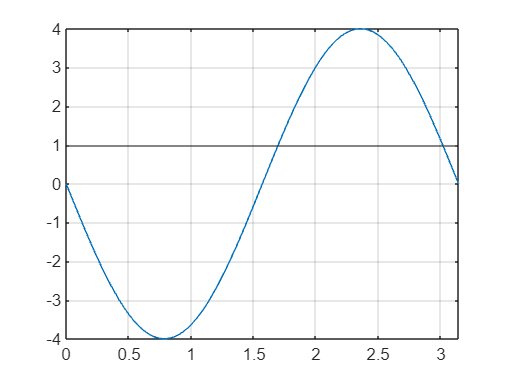

% Regla de Trapezio
clear
syms f(x)
syms n real

f(x) = sin(x)^2; h = pi / n;
d3f(x) = diff(f, x, 3);
f = matlabFunction(f);

clf('reset')
fplot(d3f(x), [0, pi])
yline(1)
grid on

Error(n) = h^3 / 12 * 4;
n0 = eval(solve( 1e-5 == Error(n)))

n0 = 101.1058

n0 = ceil(n0)

n0 = 102

I = traprl(f, 0, pi, 102)

I = 1.5708

eval(Error(n0))

ans = 9.7393e-06

% Error asociado a Simpson
clear
syms f(x)
syms n real

f(x) = sin(x)^2; h = pi / n;
d4f(x) = diff(f, x, 3);
f = matlabFunction(f);

Error(n) = h^4 * pi * 4;
n0 = eval(solve( 1e-5 == Error(n)))

n0 =   105.1846
 -105.1846


n0 = ceil(n0(1))

n0 = 106

I = simprl(f, 0, pi, 102)

I = 1.5708

eval(Error(n0))

ans = 9.6959e-06